# Linearizovaný model synchrónneho generátora

## Úvod

Táto prednáška sa zaoberá modelom publikovaným v roku 1952 pod článkom " Effect of a Modern

Amplidyne Voltage Regulator on Underexcited Operation of Large Turbine Generators". Autormi článku

sú W. G. HEFFRON a R. A. PHILLIPS a preto sa linerarizovaný model generátora často nazýva aj

Heffron-Phillipsov model. Článok začína vetou:

It has long been known that the use of a continuously acting regulator will permit stable operation of

a synchronous generator in regions where such operation is not possible with either manual control or

regulators with dead band.

Článok ďalej pokračuje:

This paper proposes to show the steady-state limits of steam turbine generators which maybe achieved

using a standard, commercially available, continuously acting regulating system, and compares these limits

with those yielded by regulators having deadband to show the degree of improvement.

Išlo teda o diskusiu k stabilite prevádzky turbogenerátora v stave podbudenia s riadením a bez riadenia.

Analýza bola vykonaná na simulačnom modeli, ktorý sa s obmenami využíva dodnes.

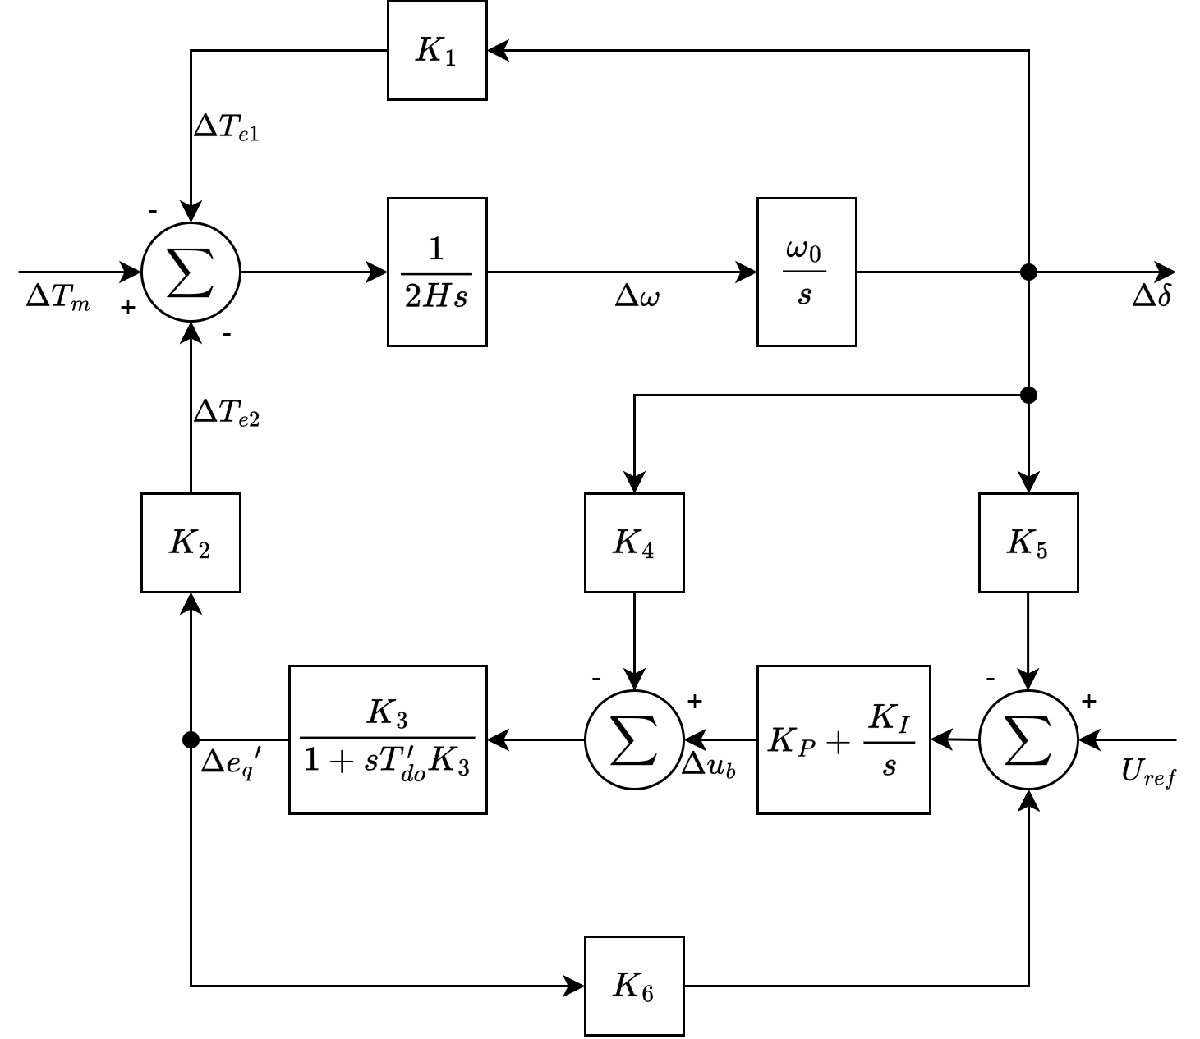

### Nelineárneho model

Pripomeňme nelineárny model synchrónneho generátora  6. rádu:

Elektrický podsystém:


$$$$T_{do}^\prime \dot e_q^\prime = -e_q^\prime + \left( X_d-X_d^\prime \right) i_d + u_b$$
$$T_{qo}^\prime \dot e_d^\prime = -e_d^\prime - \left( X_q-X_q^\prime \right) i_q$$
$$T_{do}^{\prime\prime} \dot e_q^{\prime\prime} =  -e_q^{\prime\prime} + \left( X_d^{\prime} - X_d^{\prime\prime} \right) i_d + e_q^{\prime} $$
$$ T_{qo}^{\prime\prime} \dot e_d^{\prime\prime} =  -e_d^{\prime\prime} - \left( X_q^{\prime} - X_q^{\prime\prime} \right) i_q + e_d^{\prime} $$$$


Mechanický podsystém:


$$$$ M \Delta \dot \omega = P_m - P_e $$
$$ \dot \delta =  \omega_0\Delta \omega $$$$


Ustálený stav:


$$$$ u_q = -R_s i_q + X_d^{\prime\prime} i_d + e_q^{\prime\prime} $$
$$ u_d = -R_s i_d - X_q^{\prime\prime} i_q + e_d^{\prime\prime} $$$$


Spolupráca generátora so sieťou:


$$$$ u_q = u_{sq}+r_e i_q - x_e i_d $$
$$ u_d = u_{sd}+r_e i_d + x_e i_q $$$$


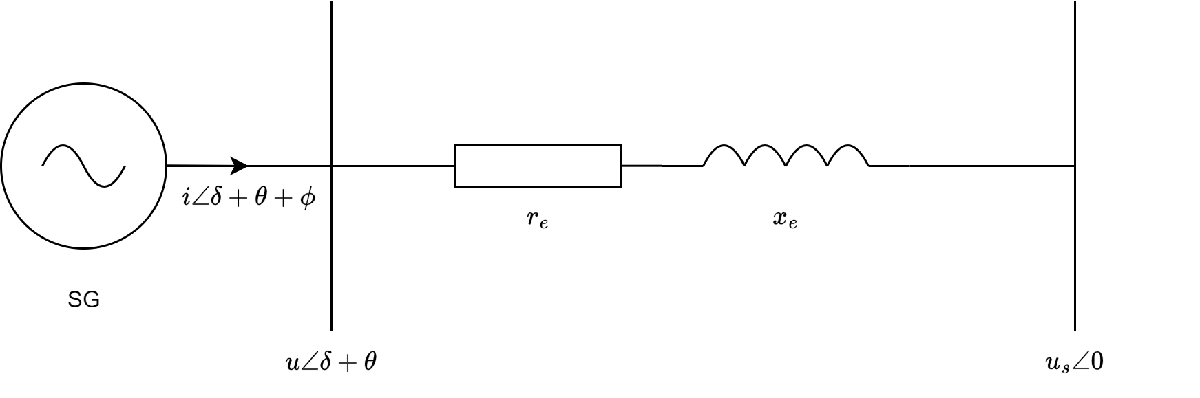

Pozrime sa teraz na náš model:

open_system('cv4model_2024_PI');

Otázky: 

- Kde sa nachádza generátor? 

- Kde sa nachádza sieť? 

- Kde sa nachádza impedancia $r_e + jx_e$ medzi sieťou a generátorom?

### Zjednodušenia nelinárneho modelu

- Nebudeme sa venovať modelu turbíny a modelu budenia.

Postup zjednodušenia elektrického podystému simulačného modelu:

Z modelu 6. rádu na model 5. rádu:

- Tento model neuvažuje vplyv vírivých prúdov v q-osi a tak $X_q = {X_q}^{\prime}$.

- Elektromotorické napätie ${E_d}^{\prime} = 0$.

Z modelu 6. rádu na model 4. rádu:

- Z modelu je odstránený vplyv tlmiacich vinutí generátora, generátor je reprezentovaný iba napätiami v prechodovom stave ${E_d}^{\prime}, {E_q}^{\prime}$, vplyv subprechodového stavu je zanedbaný.

Z modelu 4. rádu na model 3. rádu:

- Napätie v prechodovom stave ${E_d}^{\prime} = 0$ a zároveň platí $X_q = {X_q}^{\prime}$. 

Finálny zjednodušený dynamický model generátora obsahuje 3 diferenciálne rovnice:


$$$$T_{do}^\prime \dot e_q^\prime = -e_q^\prime + \left( x_d-x_d^\prime \right) i_d + u_b$$
$$ 2H \Delta \dot \omega = P_m - P_e -D\Delta\omega$$
$$ \dot \delta = \omega_0\Delta \omega $$$$


Činný výkon generátora je opísaný vzťahom:


$$$$P_e = {e_q}^\prime i_q + \left( {x_d}^\prime - x_d \right) i_d i_q$$
$$


Ustálený stav generátora:


$$$$ u_q = -r_s i_q + {x_d}^{\prime} i_d + {e_q}^{\prime} $$
$$ u_d = -r_s i_d - {x_q} i_q  $$$$


Teraz je potrebné vyriešiť ustálený stav z pohľadu sieťových veličín:

#### Sieť

Vo vektorovom tvare je vzťah medzi napätím generátora a siete daný na základe kirhoffových zákonov: 


$$$$ u \angle{\delta} = z_e i\angle{(\delta+\phi)}  + u_{s}\angle{0}  $$
$$


Vynásobením $e^{-j\delta}$ dostaneme rovnicu:


$$$$ u \angle{0} = z_e i\angle{(\phi)}  + u_{s}\angle{-\delta}  $$
$$


Úpravou a rozdelením na rovnice pre reálnu a imaginárnu zložku:


$$$$ u_q = r_e i_q - {x_e} i_d + u_{s} cos \delta $$
$$ u_d = r_e i_d + {x_e} i_q - u_{s} sin \delta $$$$


Ak navyyše zanedbáme aj odpor ${r_e} = 0$:


$$$$ u_q =  - {x_e} i_d + u_{s} cos \delta $$
$$ u_d =    {x_e} i_q - u_{s} sin \delta $$$$


#### Generátor

Ak zanedbáme odpor statorového vinutia ${r_s} = 0$ tak rovnice opisujúce ustálený stav generátora budú:


$$$$ u_q = {x_d}^{\prime} i_d + {e_q}^{\prime} $$
$$ u_d = -{x_q} i_q$$$$


Vzťah pre zložky prúdu $i_q, i_d$dostávame na základe riešenia predchádzajúcich rovníc:


$$$$ i_d = \frac{1}{A}\left[ r_e u_s sin\delta + (x_q+x_e) (u_s cos\delta - {e_q}^{\prime}) \right] $$
$$ i_q = \frac{1}{A} \left[  ({x_d}^{\prime}+x_e)  u_s sin\delta -r_e (u_s cos\delta - {e_q}^{\prime})  \right]$$ 
$$


Kde impedancia $A = ({x_d}^{\prime} + x_e)(x_q + x_e) + {r_e}^2$.

Ak navyyše zanedbáme aj odpor ${r_e} = 0$:


$$$$ i_d = \frac{1}{A}\left[ (x_q+x_e) (u_s cos\delta - {e_q}^{\prime}) \right] $$
$$ i_q = \frac{1}{A} \left[  ({x_d}^{\prime}+x_e)  u_s sin\delta  \right]$$ 
$$


Kde impedancia $A = ({x_d}^{\prime} + x_e)(x_q + x_e) $.

### Parametre modelu 3. rádu

Parametre modelu opíšeme z príkladu z cvičení:

% Parametre generátora
Tdos = 1.01*1.305/0.296; % Tdos = Tds *xd/xds
xd = 1.305;
xds = 0.296;
xq = 0.474;

H = 3.2;
D =  0;

% Impedancie transformátora a siete
xt1 = 0.08 * 13.8^2/210;
xt2 = 0.08 * 230^2/210;

xn = 0.014 * 230^2/10e3;

%^Prevod transformátora
n = 230/13.8;

Ub = 13.8;
Sb = 200;

Zb = Ub^2/Sb;

% Polovica impedancie transformátora je z pohľadu generátora za
% transformátorom
xe = (xt1 + (xt2 + xn)*1/n^2) / Zb;

Parametre ustáleného stavu siete

% Výpočet podľa P a Q
U0 = 1;
Us0 = 0.999843;

P0 = 160/Sb;
Q0 = 4.14/Sb;

% S0 = sqrt(P0^2+Q0^2);
% I0 = S0/U0;
% 
% Iq0 = P0 / Us0;
% Id0 = -(Q0-I0^2*xe)/Us0;
% 
% Uq0 = -xe*Id0 + Us0;
% Ud0 = xe*Iq0;
% A sľubujem, že naposledy preznačujem premenné
% I0 = complex(Iq0, Id0);
% U0 = complex(Uq0, Ud0);
% S0 = complex(P0, Q0);


% Výpočet podľa P a U
th0 = asin((xe*P0)/(U0*Us0));
Q0 = (U0^2-U0*Us0*cos(th0) )/xe;

% A sľubujem, že naposledy preznačujem premenné
S0 = complex(P0, Q0);
U0 = U0 * exp(j*th0);
I0 = conj(S0)/conj(U0);

Ustálený stav modelu generátora

j = complex(0,1);

E0 = U0 + j*xq*I0;

delta0 = angle(E0);
th0 =  angle(U0);
phi0 = angle(I0);

id0 =  abs(I0) * sin(phi0 - delta0);
iq0 =  abs(I0) * cos(phi0 - delta0);

ud0 =  abs(U0) * sin(th0 - delta0);
uq0 =  abs(U0) * cos(th0 - delta0);

eqs0 = uq0 - xds*id0

eqs0 = 1.0339

% počiatočná hodnota pre budiace napätie
efd0 = eqs0 - (xd-xds)*id0

efd0 = 1.3616

% počiatočná hodnota pre elektrický moment, te=pe v pomerných jednotkách
te0 = eqs0 * iq0 - (xq-xds)*id0*iq0

te0 = 0.8000

tm0 = te0

tm0 = 0.8000


Uref0 = abs(U0)

Uref0 = 1

## Model generátora 3. rádu a siete, simulácia

Model 3. rádu neobsahuje vplyv tlmiacich vinutí a preto je tento vplyv nahrádzaný tlmením D v pohybovej

rovnici.

D = 15;

Parametre rebulátora napätia:

Kp = 20;
Ki = 5;

#### Prechodové charakteristiky

Nelineárny model 3. rádu riešený pomocou ode-solvera

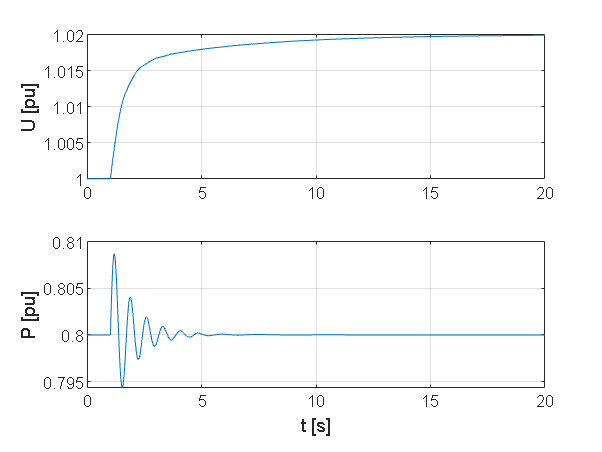

% Parametre modelu
param = [xd, xds, xq, Tdos, H, D, xe, ...
    efd0, tm0, Us0, Uref0, Kp, Ki];

x0 = [delta0, 0, eqs0, efd0];
tspan = [0:20e-3:20]';

inputVectorData = ones(size(tspan));
inputVectorData(tspan > 1) = 1.02;

opts = odeset('RelTol',1e-4,'AbsTol',1e-4);
[t, x] = ode23tb(@(t,x)modelSG3(t, x, ...
inputVectorData, tspan, param), tspan, x0, opts);

modelSG3plot;

Výstup modelu uložíme do štruktúry model3

model3.t = t;
model3.U = U;
model3.P = Te;

Spustíme simuláciu modelu v SimScape Electrical

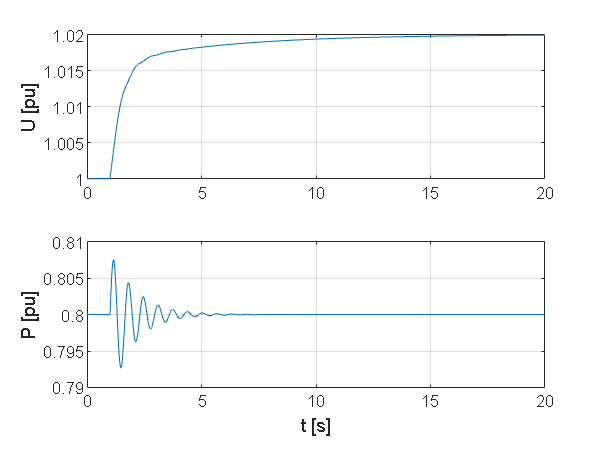

simout = sim('cv4model_2024_PI.slx');

modelSE.t = simout.sigsOut.get("Pe").Values.Time;
modelSE.U = simout.sigsOut.get("U").Values.Data;
modelSE.P = simout.sigsOut.get("Pe").Values.Data;

modelSEplot;

Porovnanie simulačných modelov:

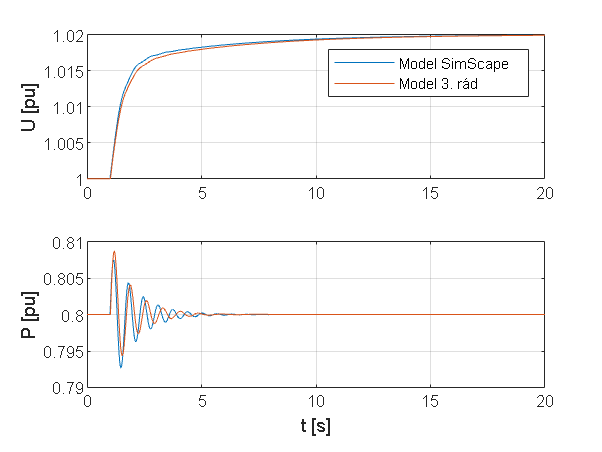

modelPlotPorovnanie;

#### Kritérium NRMSE

Porovnanie výstupov modelu a referenčných údajov sa v praxi často vyjadruje pomocou kritéria NRMSE

(Normalized Root Mean Squared Error). Referenčné údaje sú v tomto prípade simulované dáta z modelu v

SimScape Electrical. Model, ktorého presnosť chceme posudzovať je model 3. rádu.


$$NRMSE=\frac{||y_{ref}-y||}{||y_{ref}-\overline{y_{ref}}||}$$


$y$ sú údaje modelu, ktorého podobnosť chceme ohodnotiť.

$y_{ref}$ sú referenčné údaje, napr merané dáta, ktorým sa má model podobať. V našom prípade to budú údaje modelu v SimScape Electrical.

$\overline {y_{ref}}$ je strednou hodnotou referenčných údajov.

Porovnanie prechodových vlastností simulačných modelov:

modelPlotPorovnanie;


% NRMSE
[~, FitU] = nrmse(modelSE.U,modelSE.t,model3.U,model3.t, 20);
[~, FitP] = nrmse(modelSE.P,modelSE.t,model3.P,model3.t, 5);
fprintf("Podobnosť napätia modelu je: %3.3f %% \n", FitU)

Podobnosť napätia modelu je: 94.089 % 


fprintf("Podobnosť činného výkonu modelu je: %3.3f %% \n", FitP)

Podobnosť činného výkonu modelu je: 32.718 % 


#### Frekvenčné charakteristiky

Frekvenčná charakteristika je na uáklade nelineárneho modelu 3. rádu pomocou vstupného signálu s premenlivou frekvenciou.

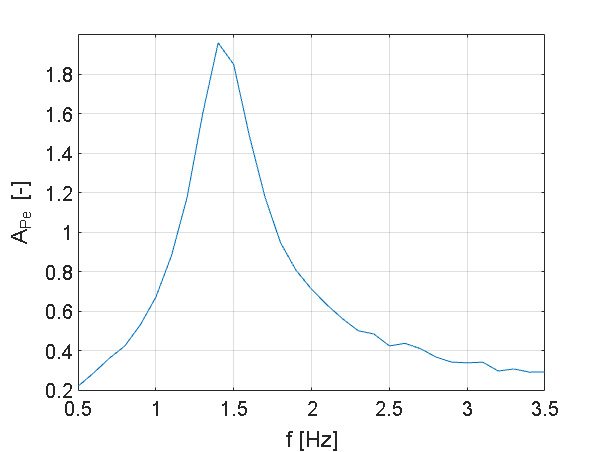

% Parametre modelu
param = [xd, xds, xq, Tdos, H, D, xe, ...
    efd0, tm0, Us0, Uref0, Kp, Ki];
x0 = [delta0, 0, eqs0, efd0];

Ax = 0.01;
f = 0.5:0.1:3.5;
i= 1;
tspan = [0:20e-3:50]';

for freq = f
    inputVectorData = ones(size(tspan));
    inputVectorData(tspan > 1) = 1 + Ax*sin(2*pi*freq * tspan(tspan > 1));
    opts = odeset('RelTol',1e-4,'AbsTol',1e-4);
    [t, x] = ode23tb(@(t,x)modelSG3(t, x, ...
        inputVectorData, tspan, param), tspan, x0, opts);
    A = (xds+xe)*(xq+xe);
    id = 1/A*(xq+xe)*(Us0*cos(x(:,1))-x(:,3));
    iq = 1/A*(xds+xe)*Us0*sin(x(:,1));
    Pe = x(:,3).*iq - (xq-xds)*id.*iq;
    dPe = Pe(t < max(t) & t > max(t)-5) - 0.8;
    Ay = max(dPe);
    AmpPe(i) = Ay/Ax;
    i = i+1;
end

model3.AmpPe = AmpPe;
model3.f = f;

figure
plot(f, AmpPe)
xlabel('f [Hz]');
ylabel('A_{Pe} [-]');
grid;    

Frekvenčná charakteristika nelineárneho modelu v SimScape Electrical je nájdená pomocou funkcie *linearize*.

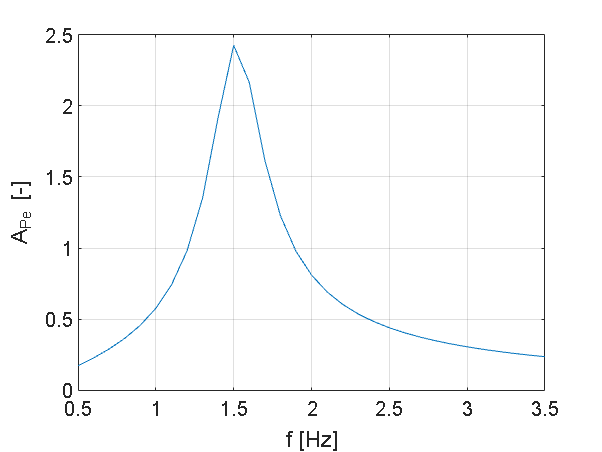

% Linearizacia
io(1) = linio('cv4model_2024_PI/Sum',1,'input'); % Vstup
io(2) = linio('cv4model_2024_PI/Sum3',1,'output'); % Vystup
linsys = linearize('cv4model_2024_PI',io); % Linearizacia
% Frekvencna charakteristika
f = 0.5:0.1:3.5; % Frekvencia
Hfreq = freqresp(linsys, 2*pi*f); % Frekvecny model
Hfreqn = permute(Hfreq, [3 2 1]); % Zmena poradia vektorov
AmpPe = abs(Hfreqn); % Amplituda frekvencneho modelu
modelSE.AmpPe = AmpPe;
modelSE.f = f;
figure
plot(f, AmpPe); % Vykreslenie
xlabel('f [Hz]');
ylabel('A_{Pe} [-]');
grid;

Porovnanie frekvenčných charakteristík simulačných modelov

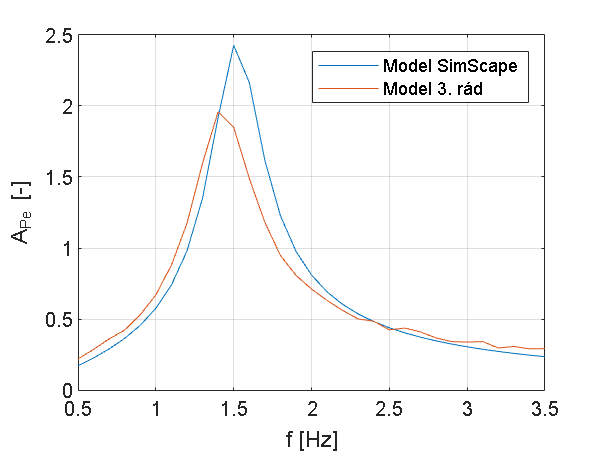

modelPlotPorovnanieFCH;


% NRMSE
[~, FitAmpPe] = nrmseFCH(modelSE.AmpPe,modelSE.f,model3.AmpPe,model3.f);
fprintf("Podobnosť FCH výkonu modelu je: %3.3f %% \n", FitAmpPe);

Podobnosť FCH výkonu modelu je: 65.941 % 


## Heffron-Phillipsov model

Nelinearita  modelu 3. rádu spočíva hlavne v rovniciach, ktoré opisujú výkon generátora:


$$$$P_e = {e_q}^\prime i_q + \left( {x_d}^\prime - x_d \right) i_d i_q$$
$$


, zložky prúdu:


$$$$ i_d = \frac{1}{A}\left[ (x_q+x_e) (u_s cos\delta - {e_q}^{\prime}) \right] $$
$$ i_q = \frac{1}{A} \left[  ({x_d}^{\prime}+x_e)  u_s sin\delta  \right]$$ 
$$


Kde impedancia $A = ({x_d}^{\prime} + x_e)(x_q + x_e) $.

a zložky napätia:


$$$$ u_q =  - {x_e} i_d + u_{s} cos \delta $$
$$ u_d =    {x_e} i_q - u_{s} sin \delta $$$$


Heffron Philipsov model je odvodený pomocou linearizácie nelineárneho modelu 3. rádu. V prvom rade je potrebné linearizovať zložky prúdu $i_q$ a $i_d$:


$$$$ \Delta i_d = C_1 \Delta \delta + C_2 \Delta {e_q}^{\prime} $$
$$ \Delta i_q = C_3 \Delta \delta + C_4 \Delta {e_q}^{\prime} $$ 
$$


Pre konštanty $C_1$až $C_2$ platí:


$$$$ C_1 = \frac{1}{A}\left[ -(x_q+x_e) (u_s sin\delta_0 \right] $$
$$ C_1 = -\frac{1}{A}\left[ x_q+x_e\right] $$

$$ C_3 = \frac{1}{A} \left[  ({x_d}^{\prime}+x_e)  u_s cos\delta_0  \right]$$ 
$$ C_4 = 0$$ $$


C1 = 1/A*(-(xq + xe)*Us0 * sin(delta0));
C2 = -1/A*(xq + xe);
C3 = 1/A*((xds + xe)*Us0 * cos(delta0));
C4 = 0;

Pre zložky zmien napätia potom platí:


$$$$ \Delta u_d = {x_d}^{\prime}C_1 \Delta \delta + (1+{x_d}^{\prime}C_2) \Delta {e_q}^{\prime} $$
$$ \Delta u_q = -x_qC_3 \Delta \delta -x_q C_4 \Delta {e_q}^{\prime} $$ 
$$


#### Mechanický podsystém

Zmena činného výkonu generátora je daná:


$$$$\Delta P_e = K_1 \Delta  \delta + K_2 \Delta {e_q}^{\prime}$$
$$


Konštanty $K_1
$ a $K_2$ sú dané ako:


$$$$ e_{q0} = {e_{q0}}^{\prime} - (x_q -{x_d}^{\prime}) i_{d0}$$
$$ K_1 = {e_{q0}C_3 -(x_q -{x_d}^{\prime}) i_{d0}C_1$$
$$ K_2 = {e_{q0}C_4+i_{q0}-(x_q -{x_d}^{\prime}) i_{q0}C_2$$
$$


eq0 = eqs0 - (xq - xds)*id0;
K1 = eq0*C3 - (xq - xds)*iq0*C1;
K2 = eq0*C4 + iq0 - (xq - xds)*iq0*C2;

Po linearizácii sa mechanický podsystém generátora zmení na:


$$$$ 2H \Delta \dot \omega = \Delta P_m - \Delta P_e -D\Delta\omega$$
$$ \Delta \dot \delta = \omega_0\Delta \omega $$$$


Dosadením za $ \Delta P_e$:


$$$$ \Delta \dot \omega = \frac{1}{2H}( -K_1  \Delta \delta  -D\Delta\omega -K_2 \Delta {e_q}^{\prime} + \Delta P_m)$$
$$ \Delta \dot \delta = \omega_0\Delta \omega $$$$


#### Elektrický podsystém

Linearizáciou rovnice pre ${e_{q}}^{\prime}$ dostávame vzťah:


$$$$ T_{do}^{\prime} \Delta \dot {e_q}^\prime = \Delta u_b - \Delta {e_q}^\prime + (x_d - {x_d}^{\prime}) (C_1 \Delta \delta + C_2 \Delta {e_q}^{\prime} )$$$$


Zavedieme konštanty $K_3$ a $K_4$ sú dané ako:


$$$$ K_3 = \frac{1}{1-(x_d -{x_d}^{\prime})C_2} $$
$$ K_4 = -(x_d -{x_d}^{\prime})C_1 $$
$$


Výsledná linearizovaná rovnica:


$$$$ \Delta \dot {e_q}^\prime = \frac{1}{T_{do}^\prime}( -K_4 \Delta \delta - \frac{1}{K_3} \Delta {e_q}^\prime +  \Delta u_b)$$$$


K3 = 1/(1-(xd-xds)*C2);
K4 = -(xd-xds)*C1;

#### Napätie generátora

Veľkosť napätia generátora je daná ako:


$$U = \sqrt{u_q^2 + u_d^2} $$


Ak tento vzťah linearizujeme dostávame:


$$\Delta U = \frac{u_{d0}}{U_0} \Delta u_d +  \frac{u_{q0}}{U_0} \Delta u_q = K_5 \Delta \delta + K_6 \Delta {e_q}^{\prime}$$


Pre konštanty $K_5$ a $K_6$ platí:


$$$$ K_5 = -\frac{u_{d0}}{U_0} x_q C_3 + \frac{u_{q0}}{U_0} {x_d}^{\prime} C_1$$
$$ K_5 = -\frac{u_{d0}}{U_0} x_q C_4 + \frac{u_{q0}}{U_0} (1+{x_d}^{\prime}) C_2$$
$$


K5 = -ud0/abs(U0)*xq*C3 + uq0/abs(U0)*xds*C1 ;
K6 = -ud0/abs(U0)*xq*C4 + uq0/abs(U0)*(1+xds*C2);

#### Model regulátora napätia

Zmena regulačnej odchýlky napätia je v tvare:


$$\Delta e = \Delta U_{ref} - \Delta U$$


Zaveďme stavovú veličinu pre integračnú zložku regulátora $\Delta \dot{u}_i = K_i \Delta{e}$. Budiace

napätie bude v tomto zjednodušenom prípade priamo výstupom regulátora:


$$\Delta u_b = \Delta u_i + K_p \Delta e =  \Delta u_i + K_p (\Delta U_{ref} - K_5 \Delta \delta - K_6 \Delta {e_q}^{\prime})$$


$\Delta \dot{u}_i = K_i \Delta{e} = K_i (\Delta U_{ref} - K_5 \Delta \delta - K_6 \Delta {e_q}^{\prime})$.

Dosadením $\Delta u_b$ do rovnice pre elektrický podsystém:


$$$$ \Delta \dot {e_q}^\prime = \frac{1}{T_{do}^\prime}( -K_4 \Delta \delta - \frac{1}{K_3} \Delta {e_q}^\prime +  \Delta u_i + K_p (\Delta U_{ref} - K_5 \Delta \delta - K_6 \Delta {e_q}^{\prime}))$$$$


Úpravou:


$$$$ \Delta \dot {e_q}^\prime = \frac{1}{T_{do}^\prime}( (-K_pK_5-K_4)\Delta \delta + (-K_p K_6 -1/K_3) \Delta {e_q}^\prime +  \Delta u_i + K_p \Delta U_{ref} )
$$


#### Model v stavovom opise


$$$$ \Delta \dot \delta = \omega_0\Delta \omega $$
$$ \Delta \dot \omega = \frac{1}{2H}( -K_1  \Delta \delta  -D\Delta\omega -K_2 \Delta {e_q}^{\prime} + \Delta P_m)$$
$$



$$$$ \Delta \dot {e_q}^\prime = \frac{1}{T_{do}^\prime}( (-K_pK_5-K_4)\Delta \delta + (-K_p K_6 -1/K_3) \Delta {e_q}^\prime +  \Delta u_i + K_p \Delta U_{ref} )
$$



$$\Delta \dot{u}_i = K_i (\Delta U_{ref} - K_5 \Delta \delta - K_6 \Delta {e_q}^{\prime})$$


% x = [delta w eqs ui]
w0 = 2*pi*50;

A = [0                  w0       0                  0;
    -K1/(2*H)           -D/(2*H) -K2/(2*H)          0;
    -(Kp*K5+K4)/Tdos    0        -(Kp*K6+1/K3)/Tdos 1/Tdos;
    -Ki*K5              0        -Ki*K6             0];

B = [0       0;
     1/(2*H) 0;
     0       Kp/Tdos;
     0       Ki];

C = [K1 0 K2 0;
      0 1 0  0;
     K5 0 K6 0];

hfModel = ss(A,B,C,[])

hfModel =
 
  A = 
              x1         x2         x3         x4
   x1          0      314.2          0          0
   x2    -0.2626     -2.344    -0.1599          0
   x3  -0.003949          0     -2.163     0.2246
   x4     0.2538          0     -1.595          0
 
  B = 
           u1      u2
   x1       0       0
   x2  0.1562       0
   x3       0   4.491
   x4       0       5
 
  C = 
             x1        x2        x3        x4
   y1     1.681         0     1.024         0
   y2         0         1         0         0
   y3  -0.05076         0    0.3191         0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.


% Stabilita
eig(A)

ans =   -1.1731 + 9.0052i
  -1.1731 - 9.0052i
  -0.2006 + 0.0000i
  -1.9596 + 0.0000i


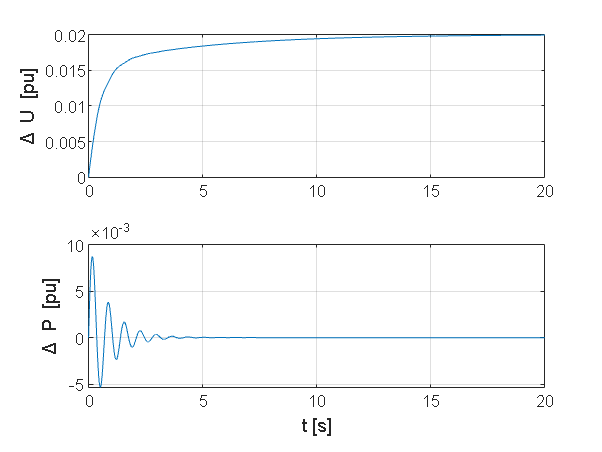

% Prechodová charakteristika
[y,t] = step(0.02*hfModel,modelSE.t);
modelHF.t = t;
modelHF.U = y(:,3,2);
modelHF.P = y(:,1,2);
figure
tiledlayout(2,1)
nexttile
plot(modelHF.t, modelHF.U)
ylabel('\Delta U [pu]')
grid;
nexttile
plot(modelHF.t, modelHF.P)
ylabel('\Delta P [pu]')
xlabel('t [s]')
grid;

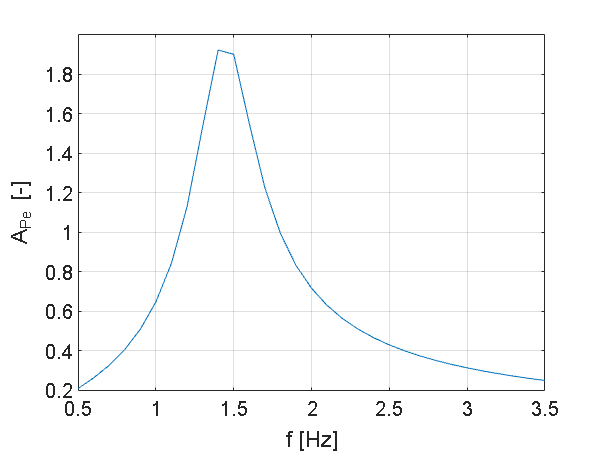

% Frekvencna charakteristika
f = 0.5:0.1:3.5; % Frekvencia
Hfreq = freqresp(hfModel, 2*pi*f); % Frekvecny model
Hfreqn = permute(Hfreq(1,2,:), [3 2 1]); % Zmena poradia vektorov
AmpPe = abs(Hfreqn); % Amplituda frekvencneho modelu
modelHF.AmpPe = AmpPe;
modelHF.f = f;
figure
plot(f, AmpPe); % Vykreslenie
xlabel('f [Hz]');
ylabel('A_{Pe} [-]');
grid;

% NRMSE
[~, FitU] = nrmse(modelSE.U - abs(U0),modelSE.t-1,modelHF.U,modelHF.t, 20);
[~, FitP] = nrmse(modelSE.P - abs(P0),modelSE.t-1,modelHF.P,modelHF.t, 5);
fprintf("Podobnosť napätia modelu je: %3.3f %% \n", FitU)

Podobnosť napätia modelu je: 91.308 % 


fprintf("Podobnosť činného výkonu modelu je: %3.3f %% \n", FitP)

Podobnosť činného výkonu modelu je: 48.341 % 


Porovnanie frekvenčných charakteristík simulačných modelov

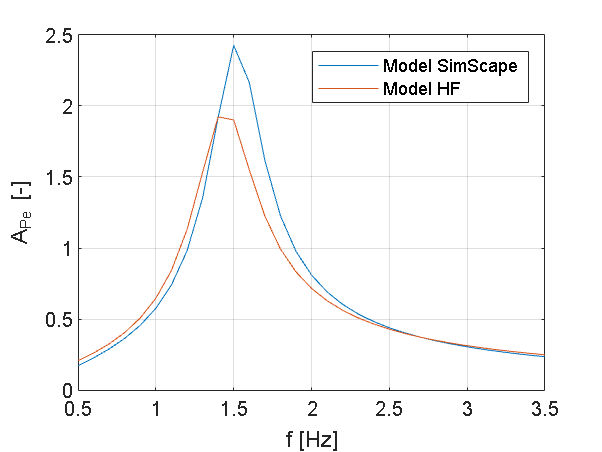

modelHFPlotPorovnanieFCH;


% NRMSE
[~, FitAmpPe] = nrmseFCH(modelSE.AmpPe,modelSE.f,modelHF.AmpPe,modelHF.f);
fprintf("Podobnosť FCH výkonu HF modelu je: %3.3f %% \n", FitAmpPe);

Podobnosť FCH výkonu HF modelu je: 70.075 % 
